# **Visualisation of Isosurfaces wihtin a reconstructed APT tip**

**Voxelisation of atom probe data in 3D, calculating concentrations, creating isosurfaces**

In order to visualise isosurfaces with an APT data set, it is necessary to voxelise the data and calculate the corresponding concentrations. Therefore, the reconstruction of the APT data set has to be done beforehand.

Also, it is essential, that the decomposed pos variable (*pos*) is present in the workspace. These steps are extensively described in the live script ***FirstSteps***.

In the first step, a set of grid vectors in 3D binning is created by the function *binVectorsFromDistance*. As inputs the distance variable and the bin width need to be specified. For the 3D binning the x, y, and z coordinates of the pos file are predestined as the *dist* input. The bin width can be either isotropic (e.g., [1 1 1] or anisotropic (e.g., [1 2 2]), whereas the positions in *dist* correspond with the position within *bin*. Here, as mode only *'distance'* is possible since the binning needs to be executed in three dimensions.

dist = [pos.x pos.y pos.z]; % distance variable for the binning
bin = [1.5 1.5 1.5]; % bin width of each voxel in the direction of the defined distances, in nm
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates the bin centers and bin edges of a grid
 

In the next section the voxelisations of both the point cloud stored in *pos* and for the specific ion species, of which the isosurface should be created, is performed. Also, the concentration of the input species is calculated

gridVec = binCenters; % renaming of bin centers, which will act as grid vectors
vox = posToVoxel(pos,gridVec); % voxelisation of all species
species = {'C'}; % input of the wanted species, e.g. {'H' 'C'}
voxIon = posToVoxel(pos,gridVec,species); % voxelisation of only the input species
conc = voxIon./vox; % calculation of the concentration of the wanted species
 

In the final step the isosurface is calculated and subsequently visualised. The *isovalue* can be any number between 0 and 100 (in at.%). For the visualisation, a *RGB* color code for the faces must be defined.

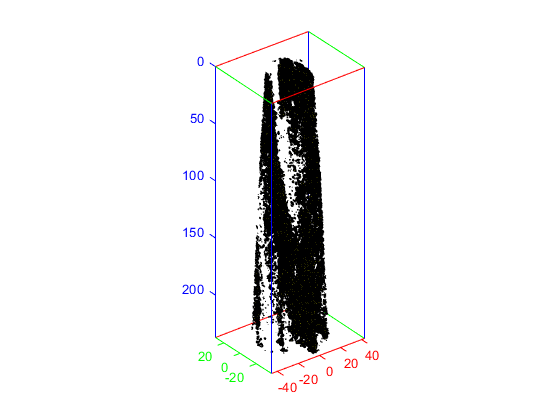

isovalue = "25"; % specification of the isovalue in at.%
fv = isosurface(gridVec{2},gridVec{1},gridVec{3},conc,isovalue); % creation of the isosurface with faces and vertices
RGB = [1 1 0]; % RGB color code for the isosurface faces
p = patch(fv, 'FaceColor', RGB); axis equal; rotate3d on; % visualisation of the created isosurface
axisSpatialAptify; % change into APT common view